# Machine Learning: Programming Exercise 2 

## Logistic Regression

In this exercise, you will implement logistic regression and apply it to two different datasets.

### Files needed for this exercise

- `ex2.mlx` - MATLAB Live Script that steps you through the exercise

- ex2data1.txt - Training set for the first half of the exercise

- ex2data2.txt - Training set for the second half of the exercise

- `submit.m` - Submission script that sends your solutions to our servers

- `mapFeature.m` - Function to generate polynomial features

- `plotDecisionBoundary.m` - Function to plot classifier's decision boundary

- *`plotData.m` - Function to plot 2D classification data

- *`sigmoid.m` - Sigmoid function

- *`costFunction.m` - Logistic regression cost function

- *`predict.m` - Logistic regression prediction function

- `*costFunctionReg.m` - Regularized logistic regression cost function

****indicates files you will need to complete***

#### Confirm that your Current Folder is set correctly

Click into this section, then click the 'Run section' button above. This will execute the `dir` command below to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex2' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

dir

### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Logistic Regression

In this part of the exercise, you will build a logistic regression model to predict whether a student gets admitted into a university. Suppose that you are the administrator of a university department and you want to determine each applicant's chance of admission based on their results on two exams. You have historical data from previous applicants that you can use as a training set for logistic regression. For each training example, you have the applicant's scores on two exams and the admissions decision.

    Your task is to build a classification model that estimates an applicant's probability of admission based the scores from those two exams. `ex2.mlx` will guide you through the exercise. To begin, run the code below to load the data into MATLAB.

% Load Data
% The first two columns contain the exam scores and the third column contains the label.
data = load('ex2data1.txt');
X = data(:, [1, 2]); y = data(:, 3);

### 1.1 Visualizing the data

Before starting to implement any learning algorithm, it is always good to visualize the data if possible. The code below will load the data and display it on a 2-dimensional plot by calling the function `plotData`. You will now complete the code in `plotData` so that it displays a figure like Figure 1, where the axes are the two exam scores, and the positive and negative examples are shown with different markers.

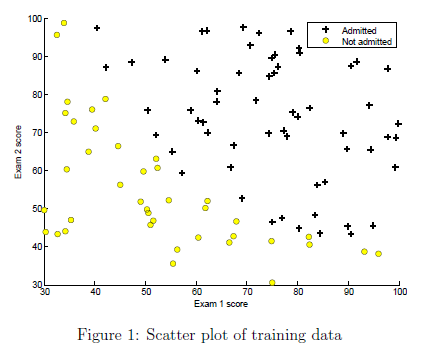

To help you get more familiar with plotting, we have left `plotData.m` empty so you can try to implement it yourself. However, this is an optional (ungraded) exercise. We also provide our implementation below so you can copy it or refer to it. If you choose to copy our example, make sure you learn what each of its commands is doing by consulting the MATLAB documentation.

Once you have added your own or the above code to `plotData.m`, run the code in this section to call the `plotData` function.

% Plot the data with + indicating (y = 1) examples and o indicating (y = 0) examples.
plotData(X, y);
 
% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')

% Specified in plot order
legend('Admitted', 'Not admitted')

### 1.2 Implementation

#### 1.2.1 Warmup exercise: sigmoid function

Before you start with the actual cost function, recall that the logistic regression hypothesis is defined as:


$$ h_{\theta}(x) = g(\theta^Tx),$$


where function $g$ is the sigmoid function. The sigmoid function is defined as:


$$g(z) = \frac{1}{1+e^{-z}}$$


    Your first step is to implement this function in `sigmoid.m` so it can be called by the rest of your program. When you are finished, try testing a few values by calling `sigmoid(x)` in the code section below. For large positive values of `x`, the sigmoid should be close to 1, while for large negative values, the sigmoid should be close to 0. Evaluating `sigmoid(0)` should give you exactly 0.5. **Your code should also work with vectors and matrices**. For a matrix, your function should perform the sigmoid function on every element.

% Provide input values to the sigmoid function below and run to check your implementation
sigmoid(0)

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 1.2.2 Cost function and gradient

Now you will implement the cost function and gradient for logistic regression. Complete the code in `costFunction.m` to return the cost and gradient. Recall that the cost function in logistic regression is


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[

-y^{(i)} \log(h_{\theta}(x^{(i)}))- (1 -y^{(i)}) \log(1- h_{\theta}(x^{(i)}))\right],$$


and the gradient of the cost is a vector of the same length as $\theta$ where the $j$th element (for $j = 0,\; 1,\ldots, n)$ is defined as follows:


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}$$


Note that while this gradient looks identical to the linear regression gradient, the formula is actually different because linear and logistic regression have different definitions of $h_{\theta}(x)$. Once you are done, run the code sections below to set up your data and call your `costFunction` using the initial parameters of $\theta$. You should see that the cost is about 0.693 and gradients of about -0.1000,  -12.0092, and -11.2628

%  Setup the data matrix appropriately
[m, n] = size(X);

% Add intercept term to X
X = [ones(m, 1) X];

% Initialize the fitting parameters
initial_theta = zeros(n + 1, 1);

% Compute and display the initial cost and gradient
[cost, grad] = costFunction(initial_theta, X, y);
fprintf('Cost at initial theta (zeros): %f\n', cost);
disp('Gradient at initial theta (zeros):'); disp(grad);

#### 1.2.3 Learning parameters using `fminunc`

In the previous assignment, you found the optimal parameters of a linear regression model by implementing gradent descent. You wrote a cost function and calculated its gradient, then took a gradient descent step accordingly. This time, instead of taking gradient descent steps, you will use a MATLAB built-in function called `fminunc`. 

    MATLAB's `fminunc` is an optimization solver that finds the minimum of an unconstrained* function. For logistic regression, you want to optimize the cost function $J(\theta)$ with parameters. Concretely, you are going to use `fminunc` to find the best parameters $\theta$ for the logistic regression cost function, given a fixed dataset (of $X$ and $y$ values). You will pass to `fminunc` the following inputs:

- The initial values of the parameters we are trying to optimize.

- A function that, when given the training set and a particular $\theta$ computes the logistic regression cost and gradient with respect to $\theta$ for the dataset $(X, y)$

**Constraints in optimization often refer to constraints on the parameters, for example, constraints that bound the possible values *$\theta$* can take (e.g. *$\theta<1$*). Logistic regression does not have such constraints since *$\theta$* is allowed to take any real value.*

We already have code written below to call `fminunc` with the correct arguments:

- We first define the options to be used with `fminunc`. Specically, we set the `GradObj` option to `on`, which tells `fminunc` that our function returns both the cost and the gradient. This allows `fminunc` to use the gradient when minimizing the function. 

- Furthermore, we set the `MaxIter` option to 400, so that `fminunc` will run for at most 400 steps before it terminates. 

- To specify the actual function we are minimizing, we use a 'short-hand' for specifying functions with: `@(t)(costFunction(t,X,y))`. This creates a function, with argument `t`, which calls your `costFunction`. This allows us to wrap the `costFunction` for use with `fminunc`.

- If you have completed the `costFunction` correctly, `fminunc` will converge on the right optimization parameters and return the final values of the cost and $\theta$. Notice that by using `fminunc`, you did not have to write any loops yourself, or set a learning rate like you did for gradient descent. This is all done by `fminunc`: you only needed to provide a function calculating the cost and the gradient.

- Once `fminunc` completes, the remaining code will call your `costFunction` function using the optimal parameters of $\theta$. You should see that the cost is about 0.203. This final $\theta$ value will then be used to plot the decision boundary on the training data, resulting in a figure similar to Figure 2. We also encourage you to look at the code in `plotDecisionBoundary.m` to see how to plot such a boundary using the $\theta$ values.

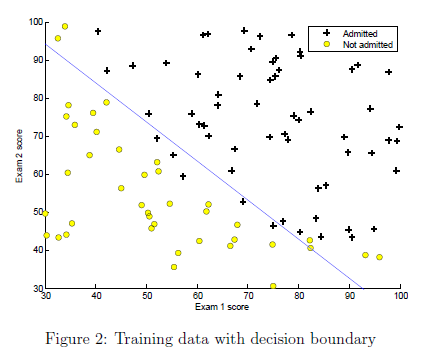

Run the code below and verify the results.

%  Set options for fminunc
options = optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 400);

%  Run fminunc to obtain the optimal theta
%  This function will return theta and the cost 
[theta, cost] = fminunc(@(t)(costFunction(t, X, y)), initial_theta, options);

% Print theta
fprintf('Cost at theta found by fminunc: %f\n', cost);
disp('theta:');disp(theta);

% Plot Boundary
plotDecisionBoundary(theta, X, y);
% Add some labels 
hold on;
% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')
% Specified in plot order
legend('Admitted', 'Not admitted')
hold off;

#### 1.2.4 Evaluating logistic regression

After learning the parameters, you can use the model to predict whether a particular student will be admitted. For a student with an Exam 1 score of 45 and an Exam 2 score of 85, you should expect to see an admission probability of 0.776. Another way to evaluate the quality of the parameters we have found is to see how well the learned model predicts on our training set. In this part, your task is to complete the code in `predict.m`. The predict function will produce '1' or '0' predictions given a dataset and a learned parameter vector $\theta$.

    After you have completed the code in `predict.m`, the code below will proceed to report the training accuracy of your classifier by computing the percentage of examples it got correct. 

%  Predict probability for a student with score 45 on exam 1  and score 85 on exam 2 
prob = sigmoid([1 45 85] * theta);
fprintf('For a student with scores 45 and 85, we predict an admission probability of %f\n\n', prob);
% Compute accuracy on our training set
p = predict(theta, X);
fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## 2. Regularized logistic regression

In this part of the exercise, you will implement regularized logistic regression to predict whether microchips from a fabrication plant passes quality assurance (QA). During QA, each microchip goes through various tests to ensure it is functioning correctly. Suppose you are the product manager of the factory and you have the test results for some microchips on two different tests. From these two tests, you would like to determine whether the microchips should be accepted or rejected. To help you make the decision, you have a dataset of test results on past microchips, from which you can build a logistic regression model.

### 2.1 Visualizing the data

Similar to the previous parts of this exercise, `plotData` is used in the code below to generate a figure like Figure 3, where the axes are the two test scores, and the positive ($y=1,$  accepted) and negative ($y=0,$ rejected) examples are shown with different markers. 

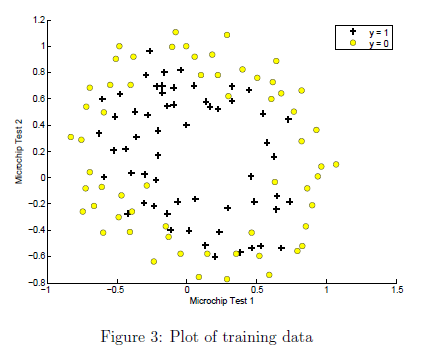

Run the code below and confirm you plot matches Figure 3.

%  The first two columns contains the X values and the third column
%  contains the label (y).
data = load('ex2data2.txt');
X = data(:, [1, 2]); y = data(:, 3);

plotData(X, y);
% Put some labels 
hold on;
% Labels and Legend
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')
% Specified in plot order
legend('y = 1', 'y = 0')
hold off;

        Figure 3 shows that our dataset cannot be separated into positive and negative examples by a straight-line through the plot. Therefore, a straightforward application of logistic regression will not perform well on this dataset since logistic regression will only be able to find a linear decision boundary.

### 2.2 Feature mapping

One way to fit the data better is to create more features from each data point. In the provided function `mapFeature.m`, we will map the features into all polynomial terms of $x_1$ and $x_2$ up to the sixth power.


$$\textrm{mapFeature}\left(x\right)=\left\lbrack \begin{array}{c}
1\\
x_1 \\
x_2 \\
x_1^2 \\
x_1 x_2 \\
x_2^2 \\
x_1^3 \\
\vdots \;\\
x_1 x_2^5 \\
x_2^6 
\end{array}\right\rbrack$$


    As a result of this mapping, our vector of two features (the scores on two QA tests) has been transformed into a 28-dimensional vector. A logistic regression classifier trained on this higher-dimension feature vector will have a more complex decision boundary and will appear nonlinear when drawn in our 2-dimensional plot. 

    Run the code below to map the features.

% Add Polynomial Features
% Note that mapFeature also adds a column of ones for us, so the intercept term is handled
X = mapFeature(X(:,1), X(:,2));

    While the feature mapping allows us to build a more expressive classifier, it also more susceptible to overfitting. In the next parts of the exercise, you will implement regularized logistic regression to fit the data and also see for yourself how regularization can help combat the overfitting problem.

### 2.3 Cost function and gradient

Now you will implement code to compute the cost function and gradient for regularized logistic regression. Complete the code in `costFunctionReg.m` to return the cost and gradient. Recall that the regularized cost function in logistic regression is


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[
-y^{(i)} \log(h_{\theta}(x^{(i)}))-(1-y^{(i)}) \log(1-h_{\theta}(x^{(i)}))\right]+\frac{\lambda}{2m}\sum_{j=1}^n{\theta_j^2},$$


Note that you should not regularize the parameter $\theta_0$. In MATLAB, recall that indexing starts from 1, hence, you should not be regularizing the `theta(1)` parameter (which corresponds to $\theta_0$) in the code. The gradient of the cost function is a vector where the $j\mathrm{th}$ element is defined as follows:


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}\qquad \mathrm{for}\;j=0,$$



$$\frac{\partial J(\theta)}{\partial \theta_j} = \left( \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}} \right)+\frac{\lambda}{m}\theta_j\qquad \mathrm{for}\;j\geq1,$$


Once you are done, run the code below to call your `costFunctionReg` function using the initial value of $\theta$ (initialized to all zeros). You should see that the cost is about 0.693.

% Initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);

% Set regularization parameter lambda to 1
lambda = 1;

% Compute and display initial cost and gradient for regularized logistic regression
[cost, grad] = costFunctionReg(initial_theta, X, y, lambda);
fprintf('Cost at initial theta (zeros): %f\n', cost);

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 2.3.1 Learning parameters using `fminunc`

Similar to the previous parts, the next step is to use `fminunc` to learn the optimal parameters. If you have completed the cost and gradient for regularized logistic regression (`costFunctionReg.m`) correctly, you should be able to run the code in the following sections to learn the parameters using `fminunc` for multiple values of $\lambda$.

### 2.4 Plotting the decision boundary

To help you visualize the model learned by this classifier, we have provided the function `plotDecisionBoundary.m` which plots the (nonlinear) decision boundary that separates the positive and negative examples. In `plotDecisionBoundary.m`, we plot the nonlinear decision boundary by computing the classifier's predictions on an evenly spaced grid and then drew a contour plot of where the predictions change from $y = 0$ to $y = 1$. After learning the parameters, the code in the next section will plot a decision boundary similar to Figure 4.

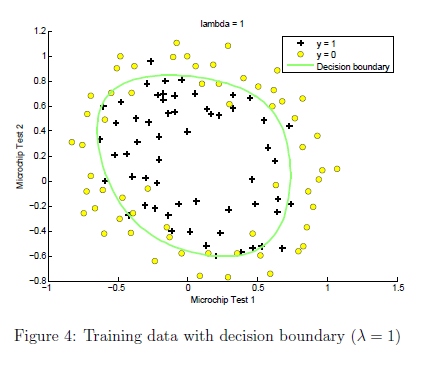

### 2.5 Optional (ungraded) exercises

In this part of the exercise, you will get to try out different regularization parameters for the dataset to understand how regularization prevents overfitting. Notice the changes in the decision boundary as you vary $\lambda$. With a small $\lambda$, you should find that the classifier gets almost every training example correct, but draws a very complicated boundary, thus overfitting the data (Figure 5). 

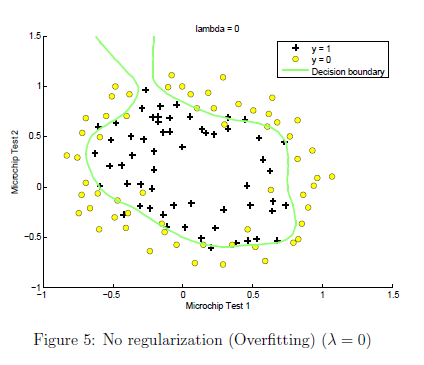

    This is not a good decision boundary: for example, it predicts that a point at $x = (0.25, 1.5)$ is accepted $(y = 1)$, which seems to be an incorrect decision given the training set. With a larger $\lambda$, you should see a plot that shows an simpler decision boundary which still separates the positives and negatives fairly well. However, if $\lambda$ is set to too high a value, you will not get a good fit and the decision boundary will not follow the data so well, thus underfitting the data (Figure 6).

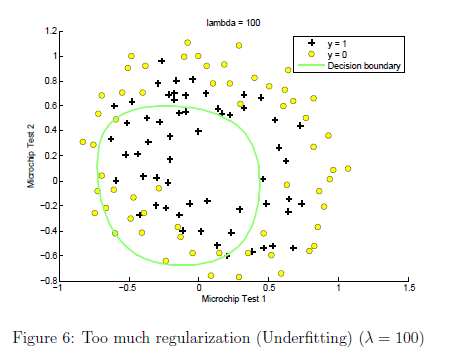

Use the control below to try the following values of $\lambda$: 0, 1, 10, 100. 

- How does the decision boundary change when you vary $\lambda$? 

- How does the training set accuracy vary?

% Initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);

lambda = 0;
% Set Options
options = optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 1000);

% Optimize
[theta, J, exit_flag] = fminunc(@(t)(costFunctionReg(t, X, y, lambda)), initial_theta, options);

g =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


g =     0.4860
    0.4879
    0.4879
    0.4943
    0.4941
    0.4966
    0.4978
    0.4978
    0.4964
    0.4949


g =     0.4724
    0.4915
    0.4919
    0.5464
    0.5386
    0.5505
    0.5595
    0.5513
    0.5344
    0.5146


g =     0.5364
    0.5680
    0.5657
    0.6478
    0.6258
    0.6350
    0.6504
    0.6317
    0.6043
    0.5670


g =     0.6613
    0.7007
    0.6903
    0.7824
    0.7379
    0.7358
    0.7610
    0.7302
    0.6993
    0.6400


g =     0.7673
    0.8025
    0.7841
    0.8630
    0.8025
    0.7880
    0.8229
    0.7847
    0.7595
    0.6845


g =     0.8501
    0.8754
    0.8521
    0.9108
    0.8374
    0.8085
    0.8554
    0.8100
    0.7956
    0.7065


g =     0.8959
    0.9130
    0.8878
    0.9313
    0.8450
    0.8002
    0.8617
    0.8077
    0.8061
    0.7054


g =     0.9184
    0.9302
    0.9038
    0.9372
    0.8343
    0.7705
    0.8498
    0.7852
    0.7993
    0.6893


g =     0.9272
    0.9358
    0.9077
    0.9343
    0.8110
    0.7261
    0.8243
    0.7486
    0.7810
    0.6660


g =     0.9274
    0.9343
    0.9042
    0.9252
    0.7813
    0.6771
    0.7904
    0.7057
    0.7571
    0.6431


g =     0.9216
    0.9279
    0.8963
    0.9121
    0.7528
    0.6345
    0.7547
    0.6650
    0.7332
    0.6263


g =     0.9122
    0.9195
    0.8886
    0.9005
    0.7389
    0.6145
    0.7307
    0.6406
    0.7180
    0.6219


g =     0.9046
    0.9150
    0.8882
    0.8993
    0.7514
    0.6288
    0.7324
    0.6437
    0.7193
    0.6323


g =     0.9046
    0.9199
    0.8999
    0.9129
    0.7895
    0.6730
    0.7604
    0.6715
    0.7367
    0.6529


g =     0.9138
    0.9328
    0.9189
    0.9326
    0.8301
    0.7163
    0.7924
    0.6989
    0.7551
    0.6672


g =     0.9252
    0.9464
    0.9373
    0.9493
    0.8604
    0.7414
    0.8126
    0.7079
    0.7619
    0.6644


g =     0.9310
    0.9539
    0.9472
    0.9575
    0.8726
    0.7425
    0.8150
    0.6954
    0.7527
    0.6432


g =     0.9296
    0.9546
    0.9488
    0.9587
    0.8712
    0.7302
    0.8063
    0.6745
    0.7353
    0.6167


g =     0.9238
    0.9515
    0.9459
    0.9563
    0.8641
    0.7167
    0.7958
    0.6580
    0.7199
    0.5968


g =     0.9164
    0.9468
    0.9411
    0.9526
    0.8560
    0.7075
    0.7883
    0.6496
    0.7102
    0.5857


g =     0.9072
    0.9407
    0.9348
    0.9481
    0.8475
    0.7024
    0.7844
    0.6483
    0.7054
    0.5809


g =     0.8960
    0.9331
    0.9270
    0.9431
    0.8388
    0.7026
    0.7860
    0.6560
    0.7069
    0.5825


g =     0.8830
    0.9246
    0.9181
    0.9382
    0.8303
    0.7104
    0.7967
    0.6771
    0.7180
    0.5923


g =     0.8733
    0.9190
    0.9120
    0.9363
    0.8244
    0.7273
    0.8193
    0.7128
    0.7406
    0.6099


g =     0.8758
    0.9223
    0.9149
    0.9400
    0.8238
    0.7475
    0.8469
    0.7513
    0.7671
    0.6264


g =     0.8891
    0.9323
    0.9247
    0.9465
    0.8266
    0.7610
    0.8670
    0.7759
    0.7840
    0.6301


g =     0.9024
    0.9414
    0.9339
    0.9514
    0.8282
    0.7663
    0.8774
    0.7862
    0.7882
    0.6199


g =     0.9116
    0.9472
    0.9399
    0.9537
    0.8269
    0.7671
    0.8819
    0.7886
    0.7831
    0.5998


g =     0.9146
    0.9487
    0.9415
    0.9529
    0.8231
    0.7659
    0.8818
    0.7863
    0.7719
    0.5766


g =     0.9116
    0.9462
    0.9389
    0.9501
    0.8191
    0.7649
    0.8790
    0.7829
    0.7619
    0.5629


g =     0.9070
    0.9428
    0.9356
    0.9477
    0.8174
    0.7654
    0.8769
    0.7816
    0.7582
    0.5615


g =     0.9044
    0.9411
    0.9339
    0.9467
    0.8173
    0.7667
    0.8766
    0.7820
    0.7583
    0.5639


g =     0.9006
    0.9386
    0.9315
    0.9456
    0.8179
    0.7697
    0.8769
    0.7835
    0.7596
    0.5691


g =     0.8948
    0.9350
    0.9279
    0.9442
    0.8193
    0.7758
    0.8784
    0.7861
    0.7619
    0.5775


g =     0.8854
    0.9291
    0.9224
    0.9425
    0.8221
    0.7875
    0.8819
    0.7895
    0.7651
    0.5907


g =     0.8725
    0.9213
    0.9149
    0.9412
    0.8266
    0.8065
    0.8887
    0.7915
    0.7671
    0.6066


g =     0.8626
    0.9157
    0.9091
    0.9421
    0.8319
    0.8293
    0.8982
    0.7871
    0.7633
    0.6164


g =     0.8673
    0.9194
    0.9113
    0.9467
    0.8365
    0.8450
    0.9059
    0.7738
    0.7512
    0.6079


g =     0.8794
    0.9273
    0.9181
    0.9514
    0.8396
    0.8495
    0.9090
    0.7613
    0.7383
    0.5888


g =     0.8848
    0.9309
    0.9216
    0.9534
    0.8414
    0.8507
    0.9100
    0.7566
    0.7315
    0.5765


g =     0.8877
    0.9330
    0.9237
    0.9548
    0.8434
    0.8518
    0.9107
    0.7542
    0.7272
    0.5682


g =     0.8909
    0.9355
    0.9266
    0.9571
    0.8486
    0.8564
    0.9129
    0.7509
    0.7173
    0.5501


g =     0.8912
    0.9366
    0.9283
    0.9598
    0.8574
    0.8652
    0.9166
    0.7485
    0.7043
    0.5278


g =     0.8853
    0.9340
    0.9264
    0.9614
    0.8670
    0.8775
    0.9213
    0.7495
    0.6913
    0.5086


g =     0.8772
    0.9295
    0.9223
    0.9611
    0.8715
    0.8845
    0.9236
    0.7530
    0.6893
    0.5085


g =     0.8730
    0.9269
    0.9198
    0.9603
    0.8715
    0.8858
    0.9238
    0.7553
    0.6919
    0.5148


g =     0.8722
    0.9264
    0.9193
    0.9599
    0.8710
    0.8856
    0.9236
    0.7559
    0.6938
    0.5184


g =     0.8716
    0.9259
    0.9188
    0.9596
    0.8706
    0.8855
    0.9235
    0.7568
    0.6960
    0.5228


g =     0.8708
    0.9255
    0.9184
    0.9594
    0.8705
    0.8857
    0.9235
    0.7583
    0.6996
    0.5299


g =     0.8701
    0.9254
    0.9188
    0.9597
    0.8715
    0.8869
    0.9241
    0.7609
    0.7050
    0.5407


g =     0.8697
    0.9268
    0.9212
    0.9612
    0.8750
    0.8901
    0.9259
    0.7654
    0.7128
    0.5564


g =     0.8706
    0.9312
    0.9278
    0.9652
    0.8834
    0.8970
    0.9300
    0.7719
    0.7218
    0.5748


g =     0.8742
    0.9395
    0.9392
    0.9717
    0.8966
    0.9069
    0.9364
    0.7790
    0.7277
    0.5863


g =     0.8798
    0.9481
    0.9499
    0.9774
    0.9076
    0.9137
    0.9416
    0.7816
    0.7255
    0.5795


g =     0.8835
    0.9513
    0.9534
    0.9788
    0.9087
    0.9120
    0.9414
    0.7773
    0.7198
    0.5666


g =     0.8839
    0.9511
    0.9530
    0.9784
    0.9068
    0.9093
    0.9399
    0.7735
    0.7165
    0.5611


g =     0.8835
    0.9506
    0.9524
    0.9780
    0.9054
    0.9077
    0.9389
    0.7714
    0.7147
    0.5590


g =     0.8825
    0.9496
    0.9513
    0.9772
    0.9030
    0.9051
    0.9371
    0.7680
    0.7121
    0.5566


g =     0.8814
    0.9484
    0.9499
    0.9762
    0.9000
    0.9020
    0.9348
    0.7641
    0.7093
    0.5544


g =     0.8800
    0.9468
    0.9478
    0.9747
    0.8954
    0.8974
    0.9314
    0.7583
    0.7053
    0.5518


g =     0.8794
    0.9453
    0.9458
    0.9729
    0.8899
    0.8925
    0.9275
    0.7514
    0.7002
    0.5488


g =     0.8822
    0.9460
    0.9455
    0.9720
    0.8867
    0.8915
    0.9253
    0.7458
    0.6945
    0.5448


g =     0.8914
    0.9513
    0.9502
    0.9746
    0.8934
    0.9020
    0.9302
    0.7487
    0.6913
    0.5403


g =     0.9039
    0.9595
    0.9585
    0.9800
    0.9097
    0.9211
    0.9419
    0.7629
    0.6937
    0.5362


g =     0.9108
    0.9643
    0.9638
    0.9834
    0.9212
    0.9325
    0.9496
    0.7749
    0.6975
    0.5335


g =     0.9124
    0.9656
    0.9653
    0.9843
    0.9244
    0.9351
    0.9514
    0.7781
    0.6987
    0.5325


g =     0.9130
    0.9660
    0.9658
    0.9846
    0.9256
    0.9357
    0.9518
    0.7787
    0.6991
    0.5322


g =     0.9136
    0.9664
    0.9664
    0.9849
    0.9272
    0.9364
    0.9521
    0.7790
    0.6993
    0.5318


g =     0.9144
    0.9669
    0.9672
    0.9853
    0.9292
    0.9369
    0.9521
    0.7784
    0.6995
    0.5316


g =     0.9154
    0.9676
    0.9682
    0.9857
    0.9321
    0.9374
    0.9517
    0.7764
    0.7002
    0.5322


g =     0.9166
    0.9685
    0.9695
    0.9863
    0.9361
    0.9380
    0.9505
    0.7715
    0.7029
    0.5359


g =     0.9177
    0.9694
    0.9711
    0.9869
    0.9413
    0.9385
    0.9475
    0.7610
    0.7116
    0.5480


g =     0.9172
    0.9700
    0.9723
    0.9873
    0.9462
    0.9386
    0.9413
    0.7416
    0.7335
    0.5781


g =     0.9129
    0.9692
    0.9717
    0.9867
    0.9472
    0.9368
    0.9303
    0.7143
    0.7750
    0.6330


g =     0.9045
    0.9665
    0.9685
    0.9845
    0.9401
    0.9316
    0.9178
    0.6951
    0.8228
    0.6920


g =     0.8996
    0.9645
    0.9656
    0.9828
    0.9322
    0.9286
    0.9150
    0.6978
    0.8449
    0.7149


g =     0.8991
    0.9642
    0.9650
    0.9826
    0.9306
    0.9297
    0.9174
    0.7040
    0.8477
    0.7145


g =     0.8992
    0.9642
    0.9649
    0.9827
    0.9306
    0.9305
    0.9186
    0.7063
    0.8469
    0.7121


g =     0.8992
    0.9642
    0.9648
    0.9827
    0.9306
    0.9309
    0.9192
    0.7072
    0.8460
    0.7100


g =     0.8992
    0.9642
    0.9647
    0.9827
    0.9306
    0.9315
    0.9201
    0.7083
    0.8439
    0.7059


g =     0.8992
    0.9640
    0.9645
    0.9827
    0.9305
    0.9321
    0.9211
    0.7093
    0.8406
    0.6997


g =     0.8991
    0.9638
    0.9642
    0.9827
    0.9301
    0.9330
    0.9223
    0.7104
    0.8350
    0.6892


g =     0.8990
    0.9635
    0.9638
    0.9825
    0.9294
    0.9342
    0.9238
    0.7112
    0.8260
    0.6728


g =     0.8986
    0.9632
    0.9634
    0.9822
    0.9279
    0.9353
    0.9249
    0.7112
    0.8128
    0.6495


g =     0.8980
    0.9632
    0.9636
    0.9816
    0.9250
    0.9357
    0.9240
    0.7088
    0.7989
    0.6256


g =     0.8971
    0.9639
    0.9652
    0.9810
    0.9212
    0.9339
    0.9189
    0.7030
    0.7969
    0.6225


g =     0.8969
    0.9655
    0.9678
    0.9809
    0.9194
    0.9305
    0.9109
    0.6966
    0.8155
    0.6547


g =     0.8973
    0.9667
    0.9694
    0.9814
    0.9209
    0.9293
    0.9069
    0.6945
    0.8332
    0.6861


g =     0.8972
    0.9668
    0.9697
    0.9816
    0.9219
    0.9295
    0.9067
    0.6946
    0.8380
    0.6949


g =     0.8970
    0.9668
    0.9696
    0.9816
    0.9221
    0.9295
    0.9067
    0.6948
    0.8389
    0.6964


g =     0.8968
    0.9667
    0.9695
    0.9816
    0.9221
    0.9294
    0.9068
    0.6949
    0.8390
    0.6969


g =     0.8966
    0.9665
    0.9693
    0.9815
    0.9219
    0.9292
    0.9067
    0.6950
    0.8391
    0.6974


g =     0.8962
    0.9662
    0.9690
    0.9813
    0.9215
    0.9288
    0.9066
    0.6952
    0.8389
    0.6981


g =     0.8956
    0.9657
    0.9685
    0.9811
    0.9209
    0.9283
    0.9064
    0.6953
    0.8384
    0.6991


g =     0.8949
    0.9651
    0.9678
    0.9807
    0.9200
    0.9275
    0.9060
    0.6949
    0.8369
    0.7007


g =     0.8944
    0.9644
    0.9669
    0.9802
    0.9189
    0.9267
    0.9051
    0.6930
    0.8336
    0.7033


g =     0.8948
    0.9640
    0.9662
    0.9799
    0.9184
    0.9269
    0.9033
    0.6867
    0.8269
    0.7073


g =     0.8980
    0.9651
    0.9669
    0.9803
    0.9207
    0.9299
    0.9002
    0.6723
    0.8161
    0.7124


g =     0.9050
    0.9686
    0.9701
    0.9822
    0.9274
    0.9367
    0.8977
    0.6521
    0.8060
    0.7160


g =     0.9123
    0.9725
    0.9739
    0.9845
    0.9351
    0.9436
    0.8982
    0.6389
    0.8054
    0.7173


g =     0.9155
    0.9743
    0.9758
    0.9856
    0.9390
    0.9464
    0.8990
    0.6365
    0.8108
    0.7189


g =     0.9159
    0.9745
    0.9761
    0.9858
    0.9398
    0.9465
    0.8987
    0.6365
    0.8134
    0.7198


g =     0.9157
    0.9744
    0.9760
    0.9857
    0.9399
    0.9462
    0.8981
    0.6365
    0.8141
    0.7200


g =     0.9155
    0.9743
    0.9759
    0.9856
    0.9398
    0.9459
    0.8978
    0.6364
    0.8141
    0.7201


g =     0.9154
    0.9742
    0.9758
    0.9856
    0.9398
    0.9457
    0.8976
    0.6362
    0.8140
    0.7201


g =     0.9153
    0.9741
    0.9757
    0.9855
    0.9397
    0.9455
    0.8973
    0.6360
    0.8137
    0.7203


g =     0.9152
    0.9739
    0.9754
    0.9854
    0.9396
    0.9453
    0.8970
    0.6357
    0.8134
    0.7205


g =     0.9149
    0.9736
    0.9751
    0.9852
    0.9396
    0.9451
    0.8966
    0.6354
    0.8128
    0.7210


g =     0.9143
    0.9730
    0.9745
    0.9850
    0.9398
    0.9450
    0.8962
    0.6350
    0.8120
    0.7219


g =     0.9127
    0.9719
    0.9733
    0.9848
    0.9407
    0.9454
    0.8963
    0.6353
    0.8108
    0.7232


g =     0.9092
    0.9697
    0.9710
    0.9846
    0.9434
    0.9474
    0.8979
    0.6374
    0.8095
    0.7249


g =     0.9024
    0.9661
    0.9676
    0.9848
    0.9490
    0.9522
    0.9028
    0.6439
    0.8089
    0.7264


g =     0.8939
    0.9625
    0.9648
    0.9859
    0.9564
    0.9592
    0.9114
    0.6557
    0.8101
    0.7253


g =     0.8896
    0.9619
    0.9651
    0.9872
    0.9609
    0.9641
    0.9190
    0.6664
    0.8124
    0.7215


g =     0.8895
    0.9626
    0.9660
    0.9877
    0.9615
    0.9652
    0.9213
    0.6695
    0.8139
    0.7196


g =     0.8898
    0.9629
    0.9662
    0.9877
    0.9611
    0.9651
    0.9212
    0.6692
    0.8144
    0.7195


g =     0.8899
    0.9629
    0.9663
    0.9876
    0.9609
    0.9650
    0.9210
    0.6688
    0.8144
    0.7195


g =     0.8900
    0.9629
    0.9662
    0.9876
    0.9608
    0.9649
    0.9207
    0.6682
    0.8145
    0.7196


g =     0.8901
    0.9629
    0.9662
    0.9875
    0.9606
    0.9648
    0.9203
    0.6675
    0.8146
    0.7198


g =     0.8902
    0.9629
    0.9661
    0.9874
    0.9604
    0.9647
    0.9198
    0.6663
    0.8148
    0.7201


g =     0.8905
    0.9628
    0.9659
    0.9872
    0.9601
    0.9645
    0.9189
    0.6645
    0.8152
    0.7208


g =     0.8910
    0.9627
    0.9656
    0.9869
    0.9597
    0.9643
    0.9176
    0.6617
    0.8159
    0.7219


g =     0.8919
    0.9624
    0.9649
    0.9864
    0.9590
    0.9641
    0.9157
    0.6576
    0.8172
    0.7242


g =     0.8939
    0.9619
    0.9637
    0.9854
    0.9580
    0.9640
    0.9130
    0.6525
    0.8199
    0.7284


g =     0.8975
    0.9609
    0.9612
    0.9835
    0.9564
    0.9643
    0.9100
    0.6479
    0.8251
    0.7362


g =     0.9036
    0.9593
    0.9566
    0.9798
    0.9541
    0.9658
    0.9091
    0.6499
    0.8345
    0.7492


g =     0.9117
    0.9578
    0.9510
    0.9744
    0.9520
    0.9690
    0.9145
    0.6674
    0.8473
    0.7650


g =     0.9185
    0.9582
    0.9486
    0.9707
    0.9512
    0.9720
    0.9250
    0.6963
    0.8578
    0.7752


g =     0.9197
    0.9592
    0.9498
    0.9705
    0.9508
    0.9728
    0.9319
    0.7159
    0.8610
    0.7756


g =     0.9178
    0.9592
    0.9506
    0.9712
    0.9504
    0.9723
    0.9329
    0.7200
    0.8602
    0.7730


g =     0.9169
    0.9591
    0.9508
    0.9715
    0.9502
    0.9719
    0.9326
    0.7200
    0.8594
    0.7717


g =     0.9168
    0.9591
    0.9508
    0.9715
    0.9500
    0.9717
    0.9324
    0.7200
    0.8590
    0.7712


g =     0.9169
    0.9591
    0.9509
    0.9714
    0.9498
    0.9716
    0.9323
    0.7201
    0.8588
    0.7709


g =     0.9170
    0.9591
    0.9509
    0.9714
    0.9497
    0.9715
    0.9322
    0.7203
    0.8586
    0.7707


g =     0.9173
    0.9592
    0.9509
    0.9713
    0.9495
    0.9714
    0.9322
    0.7208
    0.8585
    0.7705


g =     0.9178
    0.9593
    0.9509
    0.9711
    0.9492
    0.9713
    0.9321
    0.7216
    0.8583
    0.7703


g =     0.9186
    0.9594
    0.9508
    0.9709
    0.9488
    0.9711
    0.9322
    0.7228
    0.8581
    0.7701


g =     0.9201
    0.9597
    0.9507
    0.9705
    0.9481
    0.9708
    0.9323
    0.7249
    0.8579
    0.7698


g =     0.9224
    0.9601
    0.9504
    0.9699
    0.9471
    0.9705
    0.9326
    0.7280
    0.8578
    0.7696


g =     0.9259
    0.9606
    0.9495
    0.9687
    0.9456
    0.9701
    0.9333
    0.7323
    0.8579
    0.7697


g =     0.9304
    0.9613
    0.9477
    0.9670
    0.9438
    0.9700
    0.9343
    0.7363
    0.8587
    0.7707


g =     0.9340
    0.9618
    0.9452
    0.9653
    0.9426
    0.9705
    0.9352
    0.7360
    0.8607
    0.7733


g =     0.9344
    0.9620
    0.9438
    0.9650
    0.9432
    0.9714
    0.9352
    0.7296
    0.8631
    0.7765


g =     0.9327
    0.9619
    0.9441
    0.9655
    0.9440
    0.9718
    0.9345
    0.7239
    0.8641
    0.7777


g =     0.9315
    0.9617
    0.9444
    0.9657
    0.9439
    0.9717
    0.9340
    0.7227
    0.8641
    0.7773


g =     0.9313
    0.9616
    0.9444
    0.9656
    0.9437
    0.9716
    0.9338
    0.7228
    0.8640
    0.7770


g =     0.9313
    0.9616
    0.9444
    0.9655
    0.9436
    0.9715
    0.9337
    0.7228
    0.8640
    0.7769


g =     0.9314
    0.9616
    0.9445
    0.9654
    0.9433
    0.9713
    0.9335
    0.7228
    0.8640
    0.7767


g =     0.9317
    0.9617
    0.9445
    0.9653
    0.9431
    0.9712
    0.9334
    0.7229
    0.8640
    0.7767


g =     0.9321
    0.9619
    0.9446
    0.9650
    0.9427
    0.9710
    0.9331
    0.7229
    0.8641
    0.7766


g =     0.9328
    0.9622
    0.9448
    0.9647
    0.9421
    0.9708
    0.9328
    0.7229
    0.8643
    0.7767


g =     0.9340
    0.9627
    0.9452
    0.9642
    0.9413
    0.9705
    0.9322
    0.7229
    0.8647
    0.7769


g =     0.9359
    0.9635
    0.9458
    0.9634
    0.9400
    0.9700
    0.9313
    0.7230
    0.8654
    0.7773


g =     0.9388
    0.9649
    0.9467
    0.9620
    0.9379
    0.9691
    0.9298
    0.7233
    0.8667
    0.7780


g =     0.9431
    0.9670
    0.9483
    0.9596
    0.9347
    0.9674
    0.9269
    0.7241
    0.8690
    0.7788


g =     0.9487
    0.9698
    0.9505
    0.9556
    0.9298
    0.9645
    0.9218
    0.7259
    0.8727
    0.7792


g =     0.9538
    0.9728
    0.9530
    0.9502
    0.9245
    0.9600
    0.9142
    0.7296
    0.8774
    0.7777


g =     0.9556
    0.9745
    0.9546
    0.9458
    0.9222
    0.9551
    0.9064
    0.7348
    0.8810
    0.7725


g =     0.9515
    0.9735
    0.9539
    0.9460
    0.9253
    0.9529
    0.9029
    0.7388
    0.8808
    0.7644


g =     0.9460
    0.9713
    0.9519
    0.9483
    0.9285
    0.9532
    0.9040
    0.7392
    0.8784
    0.7604


g =     0.9446
    0.9705
    0.9512
    0.9490
    0.9289
    0.9534
    0.9048
    0.7387
    0.8775
    0.7604


g =     0.9442
    0.9702
    0.9510
    0.9491
    0.9289
    0.9535
    0.9052
    0.7385
    0.8772
    0.7605


g =     0.9443
    0.9702
    0.9510
    0.9491
    0.9288
    0.9535
    0.9052
    0.7386
    0.8773
    0.7605


g =     0.9445
    0.9703
    0.9510
    0.9489
    0.9286
    0.9534
    0.9051
    0.7388
    0.8774
    0.7605


g =     0.9447
    0.9704
    0.9510
    0.9488
    0.9285
    0.9533
    0.9051
    0.7389
    0.8775
    0.7604


g =     0.9450
    0.9705
    0.9511
    0.9486
    0.9282
    0.9531
    0.9049
    0.7392
    0.8778
    0.7604


g =     0.9456
    0.9707
    0.9513
    0.9483
    0.9278
    0.9529
    0.9047
    0.7396
    0.8782
    0.7604


g =     0.9465
    0.9711
    0.9516
    0.9479
    0.9271
    0.9525
    0.9044
    0.7402
    0.8789
    0.7605


g =     0.9478
    0.9717
    0.9522
    0.9472
    0.9262
    0.9519
    0.9038
    0.7410
    0.8800
    0.7608


g =     0.9500
    0.9727
    0.9531
    0.9460
    0.9246
    0.9509
    0.9028
    0.7419
    0.8818
    0.7615


g =     0.9531
    0.9742
    0.9546
    0.9442
    0.9223
    0.9492
    0.9011
    0.7429
    0.8850
    0.7636


g =     0.9572
    0.9763
    0.9570
    0.9413
    0.9188
    0.9466
    0.8982
    0.7430
    0.8901
    0.7684


g =     0.9611
    0.9789
    0.9602
    0.9374
    0.9147
    0.9430
    0.8939
    0.7402
    0.8976
    0.7788


g =     0.9619
    0.9805
    0.9629
    0.9339
    0.9125
    0.9398
    0.8896
    0.7323
    0.9058
    0.7950


g =     0.9564
    0.9795
    0.9627
    0.9338
    0.9153
    0.9399
    0.8888
    0.7221
    0.9101
    0.8091


g =     0.9481
    0.9767
    0.9599
    0.9359
    0.9199
    0.9429
    0.8919
    0.7174
    0.9084
    0.8124


g =     0.9446
    0.9751
    0.9581
    0.9372
    0.9221
    0.9448
    0.8941
    0.7174
    0.9052
    0.8097


g =     0.9443
    0.9749
    0.9578
    0.9376
    0.9225
    0.9451
    0.8945
    0.7175
    0.9039
    0.8082


g =     0.9442
    0.9748
    0.9577
    0.9377
    0.9226
    0.9452
    0.8944
    0.7174
    0.9036
    0.8079


g =     0.9442
    0.9748
    0.9577
    0.9377
    0.9226
    0.9451
    0.8944
    0.7172
    0.9034
    0.8078


g =     0.9442
    0.9748
    0.9577
    0.9377
    0.9226
    0.9451
    0.8944
    0.7171
    0.9033
    0.8077


g =     0.9442
    0.9748
    0.9577
    0.9378
    0.9226
    0.9452
    0.8944
    0.7169
    0.9031
    0.8077


g =     0.9441
    0.9748
    0.9577
    0.9379
    0.9226
    0.9452
    0.8943
    0.7166
    0.9030
    0.8076


g =     0.9440
    0.9748
    0.9577
    0.9380
    0.9225
    0.9452
    0.8942
    0.7162
    0.9027
    0.8076


g =     0.9439
    0.9747
    0.9577
    0.9381
    0.9225
    0.9451
    0.8941
    0.7155
    0.9023
    0.8077


g =     0.9437
    0.9747
    0.9577
    0.9384
    0.9224
    0.9451
    0.8937
    0.7145
    0.9018
    0.8077


g =     0.9435
    0.9746
    0.9577
    0.9388
    0.9223
    0.9449
    0.8931
    0.7129
    0.9011
    0.8079


g =     0.9434
    0.9746
    0.9577
    0.9396
    0.9221
    0.9443
    0.8916
    0.7102
    0.9002
    0.8083


g =     0.9438
    0.9749
    0.9577
    0.9411
    0.9220
    0.9428
    0.8883
    0.7055
    0.8991
    0.8088


g =     0.9458
    0.9759
    0.9579
    0.9439
    0.9223
    0.9391
    0.8810
    0.6976
    0.8987
    0.8095


g =     0.9509
    0.9781
    0.9586
    0.9481
    0.9240
    0.9324
    0.8682
    0.6867
    0.9009
    0.8103


g =     0.9581
    0.9812
    0.9605
    0.9520
    0.9269
    0.9256
    0.8558
    0.6789
    0.9067
    0.8111


g =     0.9626
    0.9831
    0.9624
    0.9534
    0.9289
    0.9234
    0.8529
    0.6795
    0.9115
    0.8107


g =     0.9628
    0.9831
    0.9624
    0.9534
    0.9294
    0.9234
    0.8540
    0.6817
    0.9120
    0.8091


g =     0.9626
    0.9830
    0.9622
    0.9529
    0.9291
    0.9233
    0.8545
    0.6828
    0.9118
    0.8087


g =     0.9624
    0.9829
    0.9621
    0.9528
    0.9292
    0.9234
    0.8546
    0.6830
    0.9117
    0.8086


g =     0.9624
    0.9829
    0.9621
    0.9528
    0.9291
    0.9234
    0.8546
    0.6830
    0.9116
    0.8086


g =     0.9624
    0.9829
    0.9621
    0.9528
    0.9291
    0.9234
    0.8546
    0.6830
    0.9116
    0.8086


g =     0.9624
    0.9829
    0.9621
    0.9528
    0.9292
    0.9234
    0.8545
    0.6829
    0.9116
    0.8086


g =     0.9624
    0.9829
    0.9621
    0.9528
    0.9292
    0.9234
    0.8545
    0.6828
    0.9115
    0.8085


g =     0.9624
    0.9829
    0.9621
    0.9529
    0.9293
    0.9235
    0.8544
    0.6825
    0.9113
    0.8085


g =     0.9624
    0.9829
    0.9621
    0.9529
    0.9294
    0.9235
    0.8543
    0.6821
    0.9111
    0.8084


g =     0.9624
    0.9829
    0.9621
    0.9531
    0.9297
    0.9237
    0.8541
    0.6814
    0.9108
    0.8082


g =     0.9625
    0.9829
    0.9621
    0.9533
    0.9300
    0.9239
    0.8538
    0.6801
    0.9102
    0.8079


g =     0.9625
    0.9829
    0.9621
    0.9537
    0.9306
    0.9243
    0.8533
    0.6779
    0.9092
    0.8073


g =     0.9626
    0.9829
    0.9621
    0.9542
    0.9316
    0.9250
    0.8525
    0.6742
    0.9078
    0.8063


g =     0.9626
    0.9828
    0.9621
    0.9551
    0.9331
    0.9263
    0.8512
    0.6678
    0.9058
    0.8045


g =     0.9626
    0.9828
    0.9617
    0.9560
    0.9351
    0.9286
    0.8495
    0.6576
    0.9037
    0.8013


g =     0.9622
    0.9826
    0.9608
    0.9563
    0.9366
    0.9319
    0.8480
    0.6451
    0.9037
    0.7972


g =     0.9618
    0.9824
    0.9597
    0.9550
    0.9361
    0.9351
    0.8488
    0.6387
    0.9080
    0.7945


g =     0.9617
    0.9825
    0.9592
    0.9529
    0.9336
    0.9357
    0.8515
    0.6439
    0.9139
    0.7950


g =     0.9618
    0.9826
    0.9594
    0.9519
    0.9316
    0.9344
    0.8526
    0.6504
    0.9164
    0.7958


g =     0.9618
    0.9826
    0.9594
    0.9519
    0.9312
    0.9338
    0.8527
    0.6523
    0.9165
    0.7958


g =     0.9617
    0.9826
    0.9594
    0.9520
    0.9312
    0.9337
    0.8526
    0.6522
    0.9163
    0.7958


g =     0.9617
    0.9826
    0.9594
    0.9521
    0.9313
    0.9337
    0.8526
    0.6519
    0.9162
    0.7957


g =     0.9617
    0.9826
    0.9594
    0.9521
    0.9314
    0.9338
    0.8525
    0.6517
    0.9162
    0.7957


g =     0.9617
    0.9826
    0.9594
    0.9522
    0.9315
    0.9339
    0.8525
    0.6515
    0.9161
    0.7956


g =     0.9617
    0.9826
    0.9594
    0.9522
    0.9316
    0.9339
    0.8524
    0.6512
    0.9161
    0.7956


g =     0.9617
    0.9826
    0.9595
    0.9523
    0.9317
    0.9341
    0.8524
    0.6508
    0.9161
    0.7956


g =     0.9617
    0.9826
    0.9595
    0.9525
    0.9320
    0.9343
    0.8523
    0.6501
    0.9160
    0.7956


g =     0.9617
    0.9826
    0.9595
    0.9527
    0.9323
    0.9346
    0.8522
    0.6492
    0.9160
    0.7957


g =     0.9617
    0.9826
    0.9596
    0.9529
    0.9329
    0.9352
    0.8520
    0.6477
    0.9161
    0.7958


g =     0.9615
    0.9826
    0.9596
    0.9533
    0.9338
    0.9361
    0.8516
    0.6452
    0.9162
    0.7962


g =     0.9613
    0.9825
    0.9595
    0.9536
    0.9353
    0.9376
    0.8511
    0.6410
    0.9167
    0.7972


g =     0.9606
    0.9821
    0.9589
    0.9537
    0.9377
    0.9401
    0.8501
    0.6341
    0.9181
    0.7993


g =     0.9589
    0.9810
    0.9570
    0.9529
    0.9412
    0.9442
    0.8486
    0.6230
    0.9212
    0.8041


g =     0.9558
    0.9786
    0.9529
    0.9502
    0.9455
    0.9496
    0.8468
    0.6086
    0.9270
    0.8129


g =     0.9515
    0.9749
    0.9465
    0.9452
    0.9497
    0.9550
    0.8462
    0.5956
    0.9347
    0.8254


g =     0.9481
    0.9713
    0.9405
    0.9403
    0.9522
    0.9582
    0.8472
    0.5902
    0.9419
    0.8384


g =     0.9486
    0.9714
    0.9403
    0.9400
    0.9515
    0.9566
    0.8467
    0.5939
    0.9436
    0.8415


g =     0.9491
    0.9719
    0.9409
    0.9403
    0.9504
    0.9553
    0.8463
    0.5970
    0.9427
    0.8396


g =     0.9492
    0.9720
    0.9409
    0.9403
    0.9499
    0.9547
    0.8463
    0.5985
    0.9423
    0.8388


g =     0.9492
    0.9719
    0.9408
    0.9403
    0.9499
    0.9547
    0.8464
    0.5985
    0.9422
    0.8387


g =     0.9492
    0.9719
    0.9408
    0.9403
    0.9499
    0.9547
    0.8464
    0.5984
    0.9422
    0.8386


g =     0.9492
    0.9719
    0.9408
    0.9403
    0.9499
    0.9547
    0.8465
    0.5984
    0.9422
    0.8386


g =     0.9492
    0.9719
    0.9408
    0.9403
    0.9500
    0.9547
    0.8465
    0.5983
    0.9422
    0.8386


g =     0.9492
    0.9719
    0.9407
    0.9403
    0.9500
    0.9547
    0.8465
    0.5983
    0.9422
    0.8385


g =     0.9492
    0.9719
    0.9407
    0.9403
    0.9500
    0.9547
    0.8466
    0.5981
    0.9422
    0.8384


g =     0.9492
    0.9719
    0.9407
    0.9404
    0.9500
    0.9548
    0.8467
    0.5979
    0.9421
    0.8383


g =     0.9492
    0.9719
    0.9406
    0.9404
    0.9501
    0.9548
    0.8468
    0.5977
    0.9421
    0.8381


g =     0.9491
    0.9718
    0.9405
    0.9405
    0.9502
    0.9548
    0.8471
    0.5973
    0.9421
    0.8378


g =     0.9491
    0.9718
    0.9404
    0.9406
    0.9503
    0.9549
    0.8476
    0.5968
    0.9420
    0.8373


g =     0.9489
    0.9717
    0.9402
    0.9407
    0.9504
    0.9549
    0.8483
    0.5962
    0.9419
    0.8366


g =     0.9487
    0.9716
    0.9400
    0.9407
    0.9504
    0.9549
    0.8498
    0.5956
    0.9416
    0.8353


g =     0.9482
    0.9714
    0.9399
    0.9402
    0.9501
    0.9547
    0.8522
    0.5954
    0.9408
    0.8329


g =     0.9471
    0.9712
    0.9399
    0.9382
    0.9487
    0.9540
    0.8564
    0.5968
    0.9387
    0.8285


g =     0.9451
    0.9711
    0.9407
    0.9330
    0.9448
    0.9524
    0.8619
    0.6010
    0.9337
    0.8205


g =     0.9423
    0.9713
    0.9427
    0.9233
    0.9372
    0.9499
    0.8675
    0.6095
    0.9250
    0.8094


g =     0.9410
    0.9720
    0.9452
    0.9146
    0.9304
    0.9483
    0.8680
    0.6148
    0.9173
    0.8025


g =     0.9411
    0.9720
    0.9456
    0.9135
    0.9309
    0.9498
    0.8660
    0.6135
    0.9177
    0.8061


g =     0.9415
    0.9719
    0.9453
    0.9146
    0.9323
    0.9501
    0.8632
    0.6108
    0.9192
    0.8088


g =     0.9415
    0.9719
    0.9452
    0.9145
    0.9321
    0.9500
    0.8633
    0.6112
    0.9190
    0.8086


g =     0.9415
    0.9719
    0.9452
    0.9146
    0.9321
    0.9499
    0.8631
    0.6110
    0.9188
    0.8084


g =     0.9415
    0.9719
    0.9452
    0.9146
    0.9321
    0.9499
    0.8631
    0.6109
    0.9188
    0.8083


g =     0.9415
    0.9719
    0.9452
    0.9146
    0.9321
    0.9499
    0.8631
    0.6108
    0.9188
    0.8082


g =     0.9415
    0.9719
    0.9452
    0.9146
    0.9321
    0.9499
    0.8631
    0.6106
    0.9187
    0.8082


g =     0.9415
    0.9718
    0.9452
    0.9146
    0.9322
    0.9500
    0.8631
    0.6104
    0.9187
    0.8080


g =     0.9414
    0.9718
    0.9451
    0.9146
    0.9322
    0.9500
    0.8630
    0.6101
    0.9186
    0.8078


g =     0.9414
    0.9718
    0.9450
    0.9146
    0.9323
    0.9501
    0.8630
    0.6096
    0.9185
    0.8076


g =     0.9413
    0.9717
    0.9449
    0.9146
    0.9324
    0.9502
    0.8630
    0.6088
    0.9183
    0.8071


g =     0.9412
    0.9715
    0.9447
    0.9146
    0.9325
    0.9505
    0.8629
    0.6075
    0.9180
    0.8064


g =     0.9410
    0.9713
    0.9443
    0.9145
    0.9328
    0.9508
    0.8629
    0.6055
    0.9176
    0.8054


g =     0.9407
    0.9709
    0.9436
    0.9143
    0.9331
    0.9513
    0.8627
    0.6020
    0.9171
    0.8037


g =     0.9400
    0.9702
    0.9424
    0.9138
    0.9334
    0.9520
    0.8625
    0.5962
    0.9163
    0.8011


g =     0.9385
    0.9689
    0.9403
    0.9128
    0.9334
    0.9527
    0.8620
    0.5865
    0.9153
    0.7975


g =     0.9358
    0.9667
    0.9367
    0.9104
    0.9322
    0.9525
    0.8610
    0.5713
    0.9145
    0.7933


g =     0.9311
    0.9635
    0.9317
    0.9055
    0.9276
    0.9497
    0.8589
    0.5521
    0.9150
    0.7909


g =     0.9257
    0.9608
    0.9279
    0.8980
    0.9175
    0.9421
    0.8569
    0.5395
    0.9189
    0.7960


g =     0.9235
    0.9608
    0.9284
    0.8919
    0.9072
    0.9339
    0.8587
    0.5460
    0.9254
    0.8088


g =     0.9243
    0.9620
    0.9300
    0.8903
    0.9051
    0.9320
    0.8628
    0.5596
    0.9298
    0.8188


g =     0.9247
    0.9622
    0.9303
    0.8906
    0.9060
    0.9324
    0.8642
    0.5649
    0.9305
    0.8216


g =     0.9248
    0.9623
    0.9303
    0.8909
    0.9064
    0.9326
    0.8641
    0.5651
    0.9302
    0.8217


g =     0.9248
    0.9622
    0.9303
    0.8910
    0.9065
    0.9327
    0.8639
    0.5645
    0.9299
    0.8214


g =     0.9248
    0.9622
    0.9302
    0.8910
    0.9064
    0.9326
    0.8638
    0.5642
    0.9298
    0.8213


g =     0.9248
    0.9622
    0.9302
    0.8909
    0.9064
    0.9326
    0.8638
    0.5642
    0.9298
    0.8212


g =     0.9248
    0.9622
    0.9302
    0.8909
    0.9063
    0.9326
    0.8639
    0.5642
    0.9298
    0.8212


g =     0.9248
    0.9622
    0.9302
    0.8909
    0.9063
    0.9326
    0.8639
    0.5642
    0.9298
    0.8212


g =     0.9247
    0.9622
    0.9302
    0.8908
    0.9062
    0.9326
    0.8640
    0.5643
    0.9298
    0.8211


g =     0.9247
    0.9622
    0.9302
    0.8906
    0.9060
    0.9325
    0.8642
    0.5644
    0.9297
    0.8210


g =     0.9246
    0.9621
    0.9302
    0.8903
    0.9057
    0.9325
    0.8644
    0.5647
    0.9297
    0.8208


g =     0.9246
    0.9621
    0.9301
    0.8899
    0.9052
    0.9323
    0.8649
    0.5652
    0.9297
    0.8205


g =     0.9244
    0.9621
    0.9301
    0.8892
    0.9044
    0.9321
    0.8655
    0.5659
    0.9297
    0.8200


g =     0.9242
    0.9620
    0.9300
    0.8881
    0.9031
    0.9318
    0.8665
    0.5672
    0.9296
    0.8191


g =     0.9239
    0.9619
    0.9299
    0.8864
    0.9010
    0.9312
    0.8680
    0.5694
    0.9296
    0.8175


g =     0.9232
    0.9617
    0.9297
    0.8835
    0.8977
    0.9301
    0.8700
    0.5729
    0.9296
    0.8145


g =     0.9220
    0.9614
    0.9296
    0.8789
    0.8927
    0.9281
    0.8720
    0.5786
    0.9298
    0.8088


g =     0.9196
    0.9609
    0.9298
    0.8718
    0.8856
    0.9245
    0.8726
    0.5876
    0.9305
    0.7977


g =     0.9151
    0.9602
    0.9306
    0.8621
    0.8782
    0.9179
    0.8669
    0.6002
    0.9325
    0.7767


g =     0.9084
    0.9595
    0.9328
    0.8538
    0.8784
    0.9086
    0.8452
    0.6114
    0.9375
    0.7458


g =     0.9044
    0.9593
    0.9353
    0.8564
    0.8964
    0.9066
    0.8050
    0.6077
    0.9465
    0.7311


g =     0.9039
    0.9575
    0.9342
    0.8671
    0.9258
    0.9243
    0.7641
    0.5786
    0.9585
    0.7598


g =     0.9006
    0.9575
    0.9356
    0.8781
    0.9296
    0.9204
    0.7452
    0.5653
    0.9549
    0.7583


g =     0.9025
    0.9584
    0.9366
    0.8823
    0.9284
    0.9206
    0.7544
    0.5653
    0.9507
    0.7549


g =     0.9033
    0.9586
    0.9369
    0.8825
    0.9279
    0.9202
    0.7544
    0.5659
    0.9492
    0.7519


g =     0.9031
    0.9585
    0.9371
    0.8823
    0.9277
    0.9203
    0.7542
    0.5665
    0.9485
    0.7509


g =     0.9030
    0.9585
    0.9372
    0.8824
    0.9278
    0.9204
    0.7540
    0.5671
    0.9485
    0.7508


g =     0.9029
    0.9585
    0.9373
    0.8824
    0.9278
    0.9204
    0.7540
    0.5673
    0.9485
    0.7509


g =     0.9029
    0.9585
    0.9373
    0.8824
    0.9278
    0.9204
    0.7541
    0.5673
    0.9486
    0.7510


g =     0.9029
    0.9585
    0.9372
    0.8824
    0.9279
    0.9205
    0.7541
    0.5672
    0.9486
    0.7510


g =     0.9028
    0.9584
    0.9372
    0.8824
    0.9279
    0.9205
    0.7542
    0.5672
    0.9486
    0.7510


g =     0.9028
    0.9584
    0.9371
    0.8823
    0.9280
    0.9206
    0.7543
    0.5670
    0.9485
    0.7510


g =     0.9028
    0.9584
    0.9371
    0.8823
    0.9281
    0.9207
    0.7544
    0.5667
    0.9485
    0.7510


g =     0.9027
    0.9583
    0.9369
    0.8823
    0.9283
    0.9209
    0.7546
    0.5662
    0.9483
    0.7509


g =     0.9027
    0.9581
    0.9367
    0.8822
    0.9286
    0.9212
    0.7548
    0.5652
    0.9482
    0.7508


g =     0.9026
    0.9579
    0.9364
    0.8820
    0.9290
    0.9217
    0.7552
    0.5635
    0.9479
    0.7506


g =     0.9025
    0.9576
    0.9359
    0.8818
    0.9298
    0.9226
    0.7557
    0.5607
    0.9474
    0.7503


g =     0.9025
    0.9572
    0.9350
    0.8814
    0.9310
    0.9240
    0.7564
    0.5557
    0.9469
    0.7502


g =     0.9026
    0.9566
    0.9335
    0.8806
    0.9330
    0.9266
    0.7575
    0.5469
    0.9463
    0.7509


g =     0.9033
    0.9558
    0.9309
    0.8790
    0.9361
    0.9310
    0.7590
    0.5314
    0.9464
    0.7539


g =     0.9055
    0.9551
    0.9263
    0.8758
    0.9407
    0.9385
    0.7611
    0.5047
    0.9487
    0.7632


g =     0.9106
    0.9555
    0.9189
    0.8698
    0.9467
    0.9496
    0.7641
    0.4639
    0.9559
    0.7845


g =     0.9192
    0.9587
    0.9102
    0.8612
    0.9520
    0.9617
    0.7671
    0.4163
    0.9679
    0.8184


g =     0.9295
    0.9650
    0.9076
    0.8550
    0.9533
    0.9694
    0.7665
    0.3858
    0.9787
    0.8506


g =     0.9373
    0.9707
    0.9146
    0.8544
    0.9495
    0.9695
    0.7596
    0.3886
    0.9830
    0.8628


g =     0.9406
    0.9733
    0.9210
    0.8550
    0.9449
    0.9673
    0.7526
    0.4007
    0.9832
    0.8622


g =     0.9400
    0.9734
    0.9231
    0.8559
    0.9431
    0.9665
    0.7515
    0.4061
    0.9817
    0.8571


g =     0.9392
    0.9729
    0.9227
    0.8550
    0.9426
    0.9667
    0.7536
    0.4068
    0.9809
    0.8545


g =     0.9390
    0.9728
    0.9225
    0.8551
    0.9426
    0.9668
    0.7541
    0.4063
    0.9806
    0.8532


g =     0.9392
    0.9729
    0.9224
    0.8552
    0.9428
    0.9669
    0.7538
    0.4057
    0.9807
    0.8536


g =     0.9393
    0.9729
    0.9225
    0.8552
    0.9428
    0.9669
    0.7538
    0.4056
    0.9807
    0.8537


g =     0.9393
    0.9729
    0.9225
    0.8552
    0.9428
    0.9669
    0.7537
    0.4055
    0.9807
    0.8537


g =     0.9394
    0.9730
    0.9226
    0.8553
    0.9428
    0.9668
    0.7535
    0.4054
    0.9808
    0.8538


g =     0.9395
    0.9730
    0.9227
    0.8553
    0.9427
    0.9668
    0.7532
    0.4052
    0.9808
    0.8539


g =     0.9396
    0.9731
    0.9229
    0.8554
    0.9426
    0.9667
    0.7527
    0.4049
    0.9809
    0.8540


g =     0.9398
    0.9732
    0.9231
    0.8556
    0.9424
    0.9665
    0.7519
    0.4044
    0.9810
    0.8543


g =     0.9400
    0.9734
    0.9235
    0.8558
    0.9420
    0.9662
    0.7506
    0.4036
    0.9812
    0.8548


g =     0.9402
    0.9736
    0.9240
    0.8562
    0.9414
    0.9655
    0.7484
    0.4023
    0.9815
    0.8557


g =     0.9405
    0.9739
    0.9249
    0.8569
    0.9402
    0.9644
    0.7449
    0.4003
    0.9820
    0.8572


g =     0.9407
    0.9744
    0.9264
    0.8583
    0.9380
    0.9625
    0.7389
    0.3970
    0.9828
    0.8597


g =     0.9407
    0.9753
    0.9291
    0.8612
    0.9341
    0.9589
    0.7286
    0.3914
    0.9840
    0.8639


g =     0.9401
    0.9769
    0.9342
    0.8678
    0.9269
    0.9523
    0.7109
    0.3819
    0.9859
    0.8707


g =     0.9383
    0.9800
    0.9435
    0.8819
    0.9140
    0.9405
    0.6816
    0.3665
    0.9883
    0.8804


g =     0.9358
    0.9851
    0.9580
    0.9075
    0.8945
    0.9229
    0.6416
    0.3457
    0.9905
    0.8907


g =     0.9367
    0.9910
    0.9738
    0.9391
    0.8744
    0.9064
    0.6121
    0.3296
    0.9911
    0.8949


g =     0.9443
    0.9949
    0.9840
    0.9603
    0.8643
    0.9014
    0.6196
    0.3300
    0.9894
    0.8902


g =     0.9495
    0.9962
    0.9879
    0.9682
    0.8637
    0.9055
    0.6371
    0.3372
    0.9875
    0.8828


g =     0.9514
    0.9966
    0.9890
    0.9702
    0.8645
    0.9085
    0.6432
    0.3408
    0.9868
    0.8794


g =     0.9516
    0.9966
    0.9892
    0.9706
    0.8644
    0.9097
    0.6444
    0.3419
    0.9866
    0.8789


g =     0.9514
    0.9966
    0.9893
    0.9706
    0.8640
    0.9098
    0.6439
    0.3429
    0.9866
    0.8788


g =     0.9510
    0.9966
    0.9892
    0.9704
    0.8638
    0.9097
    0.6435
    0.3435
    0.9866
    0.8791


g =     0.9508
    0.9966
    0.9892
    0.9703
    0.8637
    0.9096
    0.6434
    0.3439
    0.9866
    0.8791


g =     0.9507
    0.9965
    0.9891
    0.9702
    0.8636
    0.9096
    0.6434
    0.3440
    0.9866
    0.8792


g =     0.9506
    0.9965
    0.9891
    0.9701
    0.8636
    0.9097
    0.6435
    0.3441
    0.9866
    0.8791


g =     0.9506
    0.9965
    0.9891
    0.9700
    0.8636
    0.9097
    0.6435
    0.3440
    0.9866
    0.8791


g =     0.9505
    0.9965
    0.9891
    0.9700
    0.8636
    0.9097
    0.6435
    0.3440
    0.9866
    0.8791


g =     0.9505
    0.9965
    0.9891
    0.9699
    0.8636
    0.9098
    0.6436
    0.3440
    0.9866
    0.8791


g =     0.9505
    0.9965
    0.9890
    0.9699
    0.8636
    0.9098
    0.6436
    0.3440
    0.9866
    0.8791


g =     0.9505
    0.9965
    0.9890
    0.9699
    0.8636
    0.9098
    0.6436
    0.3440
    0.9866
    0.8791


g =     0.9504
    0.9965
    0.9890
    0.9698
    0.8636
    0.9098
    0.6436
    0.3440
    0.9866
    0.8792


g =     0.9504
    0.9965
    0.9890
    0.9698
    0.8636
    0.9098
    0.6436
    0.3441
    0.9866
    0.8793


g =     0.9503
    0.9965
    0.9890
    0.9698
    0.8636
    0.9098
    0.6436
    0.3441
    0.9866
    0.8794


g =     0.9503
    0.9965
    0.9890
    0.9699
    0.8636
    0.9098
    0.6436
    0.3440
    0.9866
    0.8797


g =     0.9502
    0.9965
    0.9890
    0.9700
    0.8636
    0.9097
    0.6436
    0.3439
    0.9867
    0.8801


g =     0.9502
    0.9965
    0.9891
    0.9701
    0.8635
    0.9095
    0.6437
    0.3438
    0.9867
    0.8807


g =     0.9503
    0.9965
    0.9891
    0.9705
    0.8634
    0.9093
    0.6437
    0.3434
    0.9869
    0.8816


g =     0.9503
    0.9966
    0.9893
    0.9710
    0.8631
    0.9090
    0.6439
    0.3427
    0.9871
    0.8831


g =     0.9504
    0.9967
    0.9896
    0.9719
    0.8628
    0.9085
    0.6442
    0.3415
    0.9875
    0.8853


g =     0.9505
    0.9968
    0.9900
    0.9734
    0.8623
    0.9075
    0.6447
    0.3393
    0.9881
    0.8888


g =     0.9506
    0.9970
    0.9906
    0.9758
    0.8616
    0.9058
    0.6455
    0.3354
    0.9889
    0.8941


g =     0.9504
    0.9973
    0.9915
    0.9795
    0.8609
    0.9025
    0.6469
    0.3284
    0.9901
    0.9019


g =     0.9488
    0.9976
    0.9927
    0.9850
    0.8608
    0.8954
    0.6491
    0.3161
    0.9914
    0.9128


g =     0.9439
    0.9980
    0.9942
    0.9916
    0.8638
    0.8801
    0.6531
    0.2963
    0.9926
    0.9258


g =     0.9316
    0.9983
    0.9956
    0.9969
    0.8757
    0.8494
    0.6607
    0.2712
    0.9929
    0.9363


g =     0.9078
    0.9983
    0.9967
    0.9992
    0.9041
    0.8013
    0.6754
    0.2511
    0.9909
    0.9378


g =     0.8797
    0.9977
    0.9963
    0.9997
    0.9444
    0.7815
    0.6919
    0.2416
    0.9873
    0.9308


g =     0.8999
    0.9980
    0.9967
    0.9999
    0.9595
    0.7564
    0.6947
    0.2554
    0.9782
    0.9050


g =     0.9066
    0.9961
    0.9930
    0.9998
    0.9808
    0.8074
    0.6876
    0.2645
    0.9734
    0.8753


g =     0.9024
    0.9975
    0.9957
    0.9999
    0.9691
    0.7762
    0.6921
    0.2587
    0.9766
    0.8949


g =     0.8947
    0.9971
    0.9951
    0.9998
    0.9658
    0.7937
    0.6900
    0.2725
    0.9752
    0.8878


g =     0.9016
    0.9972
    0.9951
    0.9997
    0.9589
    0.7826
    0.6726
    0.2814
    0.9748
    0.8832


g =     0.8972
    0.9970
    0.9949
    0.9997
    0.9577
    0.7770
    0.6697
    0.2813
    0.9737
    0.8808


g =     0.8951
    0.9969
    0.9948
    0.9997
    0.9563
    0.7738
    0.6671
    0.2801
    0.9731
    0.8787


g =     0.8951
    0.9969
    0.9947
    0.9996
    0.9554
    0.7728
    0.6664
    0.2792
    0.9729
    0.8774


g =     0.8955
    0.9969
    0.9947
    0.9996
    0.9550
    0.7734
    0.6674
    0.2788
    0.9728
    0.8765


g =     0.8956
    0.9969
    0.9947
    0.9996
    0.9550
    0.7740
    0.6683
    0.2790
    0.9727
    0.8762


g =     0.8955
    0.9969
    0.9947
    0.9996
    0.9551
    0.7742
    0.6688
    0.2791
    0.9726
    0.8760


g =     0.8955
    0.9969
    0.9947
    0.9996
    0.9552
    0.7742
    0.6688
    0.2792
    0.9726
    0.8759


g =     0.8954
    0.9969
    0.9947
    0.9996
    0.9552
    0.7741
    0.6687
    0.2792
    0.9726
    0.8758


g =     0.8955
    0.9969
    0.9947
    0.9996
    0.9552
    0.7740
    0.6685
    0.2792
    0.9726
    0.8758


g =     0.8955
    0.9969
    0.9947
    0.9996
    0.9552
    0.7740
    0.6685
    0.2792
    0.9726
    0.8758


g =     0.8955
    0.9969
    0.9947
    0.9996
    0.9552
    0.7740
    0.6685
    0.2792
    0.9726
    0.8758


g =     0.8955
    0.9969
    0.9947
    0.9996
    0.9552
    0.7740
    0.6685
    0.2792
    0.9726
    0.8758


g =     0.8955
    0.9969
    0.9947
    0.9996
    0.9552
    0.7740
    0.6686
    0.2793
    0.9726
    0.8758


g =     0.8955
    0.9969
    0.9947
    0.9996
    0.9552
    0.7741
    0.6687
    0.2793
    0.9726
    0.8758


g =     0.8955
    0.9969
    0.9947
    0.9996
    0.9552
    0.7741
    0.6689
    0.2794
    0.9726
    0.8758


g =     0.8954
    0.9969
    0.9947
    0.9996
    0.9552
    0.7742
    0.6691
    0.2795
    0.9726
    0.8759


g =     0.8954
    0.9969
    0.9947
    0.9996
    0.9553
    0.7743
    0.6695
    0.2796
    0.9726
    0.8759


g =     0.8952
    0.9969
    0.9947
    0.9996
    0.9554
    0.7745
    0.6700
    0.2797
    0.9726
    0.8761


g =     0.8949
    0.9969
    0.9947
    0.9996
    0.9556
    0.7748
    0.6708
    0.2798
    0.9726
    0.8763


g =     0.8945
    0.9969
    0.9947
    0.9996
    0.9559
    0.7751
    0.6717
    0.2799
    0.9726
    0.8767


g =     0.8938
    0.9969
    0.9947
    0.9996
    0.9563
    0.7755
    0.6726
    0.2799
    0.9725
    0.8773


g =     0.8927
    0.9968
    0.9947
    0.9997
    0.9568
    0.7758
    0.6733
    0.2799
    0.9724
    0.8782


g =     0.8912
    0.9968
    0.9946
    0.9997
    0.9574
    0.7759
    0.6731
    0.2798
    0.9721
    0.8798


g =     0.8891
    0.9967
    0.9945
    0.9997
    0.9582
    0.7753
    0.6703
    0.2795
    0.9716
    0.8821


g =     0.8872
    0.9966
    0.9943
    0.9997
    0.9592
    0.7729
    0.6618
    0.2794
    0.9704
    0.8854


g =     0.8875
    0.9967
    0.9942
    0.9997
    0.9604
    0.7668
    0.6436
    0.2807
    0.9680
    0.8887


g =     0.8913
    0.9970
    0.9945
    0.9998
    0.9619
    0.7549
    0.6166
    0.2860
    0.9637
    0.8892


g =     0.8958
    0.9974
    0.9952
    0.9998
    0.9629
    0.7392
    0.5928
    0.2977
    0.9580
    0.8852


g =     0.8971
    0.9977
    0.9956
    0.9999
    0.9628
    0.7286
    0.5863
    0.3096
    0.9533
    0.8807


g =     0.8944
    0.9978
    0.9958
    0.9999
    0.9616
    0.7248
    0.5930
    0.3134
    0.9513
    0.8791


g =     0.8869
    0.9976
    0.9955
    0.9999
    0.9595
    0.7242
    0.6064
    0.3109
    0.9497
    0.8784


g =     0.8759
    0.9972
    0.9949
    0.9999
    0.9574
    0.7257
    0.6163
    0.3058
    0.9491
    0.8805


g =     0.8802
    0.9973
    0.9951
    0.9999
    0.9582
    0.7251
    0.6126
    0.3077
    0.9493
    0.8797


g =     0.8791
    0.9972
    0.9949
    0.9999
    0.9591
    0.7264
    0.6067
    0.3074
    0.9484
    0.8820


g =     0.8807
    0.9971
    0.9946
    0.9999
    0.9615
    0.7299
    0.5873
    0.3137
    0.9472
    0.8890


g =     0.8787
    0.9970
    0.9945
    0.9998
    0.9604
    0.7310
    0.5914
    0.3171
    0.9485
    0.8902


g =     0.8795
    0.9970
    0.9946
    0.9998
    0.9602
    0.7308
    0.5935
    0.3182
    0.9483
    0.8891


g =     0.8801
    0.9970
    0.9946
    0.9998
    0.9599
    0.7311
    0.5937
    0.3204
    0.9484
    0.8891


g =     0.8809
    0.9971
    0.9947
    0.9998
    0.9599
    0.7314
    0.5931
    0.3214
    0.9485
    0.8895


g =     0.8814
    0.9971
    0.9948
    0.9998
    0.9601
    0.7315
    0.5928
    0.3213
    0.9486
    0.8896


g =     0.8818
    0.9971
    0.9948
    0.9999
    0.9602
    0.7316
    0.5926
    0.3210
    0.9487
    0.8897


g =     0.8819
    0.9972
    0.9948
    0.9999
    0.9603
    0.7315
    0.5926
    0.3209
    0.9487
    0.8897


g =     0.8819
    0.9972
    0.9948
    0.9999
    0.9603
    0.7316
    0.5927
    0.3209
    0.9487
    0.8897


g =     0.8819
    0.9972
    0.9948
    0.9999
    0.9603
    0.7316
    0.5927
    0.3210
    0.9487
    0.8897



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


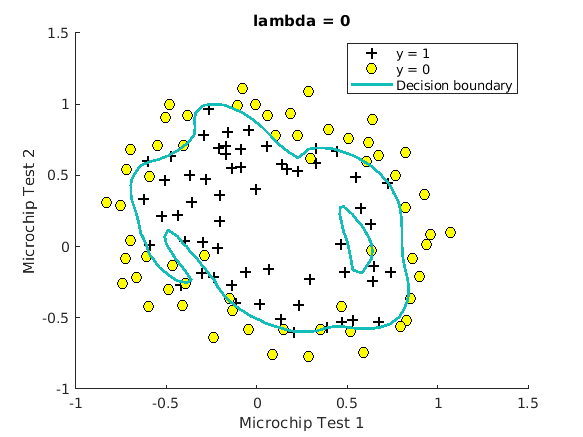

% Plot Boundary
plotDecisionBoundary(theta, X, y);
hold on;
title(sprintf('lambda = %g', lambda))

% Labels and Legend
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')

legend('y = 1', 'y = 0', 'Decision boundary')
hold off;


% Compute accuracy on our training set
p = predict(theta, X);

g =     0.8819
    0.9972
    0.9948
    0.9999
    0.9603
    0.7316
    0.5927
    0.3210
    0.9487
    0.8897



fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

Train Accuracy: 88.983051


*You do not need to submit any solutions for these optional (ungraded) exercises.*

## Submission and Grading

After completing various parts of the assignment, be sure to use the `submit` function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

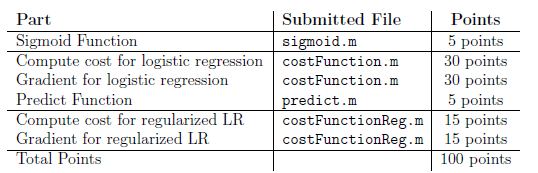

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.